clear; clc;

addpath './../classes'

function [primal_optimum, dual_optimum] = calculate_primal_and_dual_values(states)

    sdp = SDP_Symmetric_1to2_Cloner(states);
    
    [primal_optimum, ~] = sdp.solvePrimal();
    [dual_optimum,  ~] = sdp.solveDual();
end 

N_values = [10, 20, 50, 100, 200, 500, ...
    1000, 2000, 4000, 6000, 8000, 10000, ...
    20000, 40000, 60000, 80000, 100000] ;

F_theoretical = 5/6;

primal_errors = zeros(1, length(N_values) );
dual_errors = zeros(1, length(N_values) );

for N = N_values
    states = Utils.fibonacci_qubits(N);
    [primal, dual] = calculate_primal_and_dual_values( states ); 
    primal_errors(N == N_values) = abs(primal - F_theoretical);
    dual_errors(N == N_values) = abs(dual - F_theoretical);
end

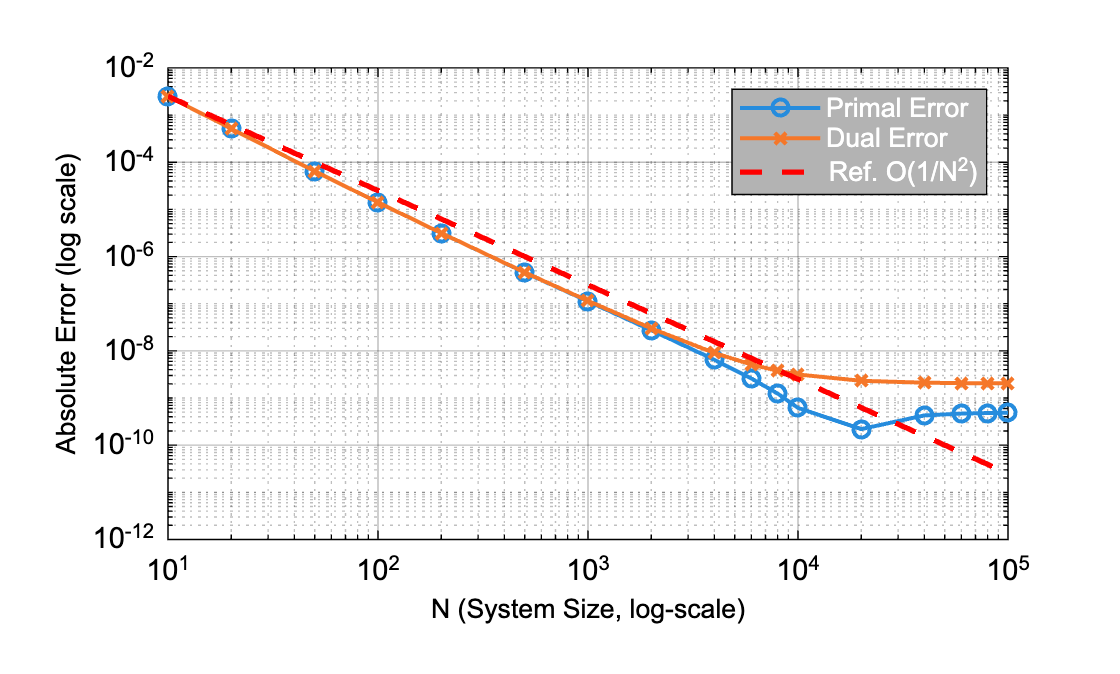

% 1. Create figure with white background
fig = figure('Color', 'w'); 

% 2. Plot data
loglog(N_values, primal_errors, '-o', 'LineWidth', 1.5, 'DisplayName', 'Primal Error');
hold on;
loglog(N_values, dual_errors, '-x', 'LineWidth', 1.5, 'DisplayName', 'Dual Error');

% 3. Reference power law line O(1/N^2) in red
C = primal_errors(1) * (N_values(1)^2); 
ref_line = C ./ (N_values.^2);
loglog(N_values, ref_line, 'r--', 'LineWidth', 2, 'DisplayName', 'Ref. O(1/N^2)');

% 4. Formatting: Font, colors, and axes
ax = gca;
set(ax, 'FontName', 'Arial', 'FontSize', 11);
set(ax, 'XColor', 'k', 'YColor', 'k'); % Black axis lines and ticks
set(ax, 'Color', 'w');                 % White plot area background

xlabel('N (System Size, log-scale)', 'Color', 'k', 'FontName', 'Arial','FontSize', 10);
ylabel('Absolute Error (log scale)', 'Color', 'k', 'FontName', 'Arial','FontSize', 10);

% Manual adjustment of the plot area to increase bottom margin
% [left, bottom, width, height]
set(gca, 'Position', [0.15, 0.20, 0.75, 0.70]); 

% 5. Legend formatting: Gray background with white text
lgd = legend('show');
set(lgd, 'Color', [0.7, 0.7, 0.7], ... % Medium gray background
          'TextColor', 'w', ...        % White text
          'FontName', 'Arial', ...
          'EdgeColor', 'k', ...
          'FontSize', 10);           % Black border for the legend box

grid on;

% 6. Export as JPG
% 'Resolution' 300 ensures high quality for publications
exportgraphics(fig, './figures/Convergence_Analysis.jpg', 'Resolution', 300);